# Regularized Zero Forcing Precoder

% Downlink
% Achievable Rate V.S. Power Parameter
% Linear Formation and Rectangular Formation

## Global Parameter

clc
clearvars

M1 = 8;
M2 = 8;
M = M1 * M2;
K = 10;

taps = 4;
freq = 20;

max_c = 40;
range = linspace(0, 20, max_c);

use = 5;

time = 100;
cyclic_prefix = 0;
shield = taps + freq + 1;

IK = eye(K);

r_in = 10;

dn = 0.5;

alpha = 0;
eta = 200;
mu = 0;


## Correlation Matrix

for i = 1 : M
    for j = 1 : M
        dist(i, j) = abs(i - j) * dn;
    end
end
exp_1D = alpha .^ dist;
arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
arg = sqrt(arg);
bsl_1D = abs(besseli(0, arg) ./ besseli(0, eta));
clear dist;

i = 1;
for c1 = 1 : M1
    for r1 = 1 : M2
        j = 1;
        for c2 = 1 : M1
            for r2 = 1 : M2
                dist(i, j) = (c2 - c1) ^ 2 + (r1 - r2) ^ 2;
                j = j + 1;
            end
        end
        i = i + 1;
    end
end
dist = sqrt(dist .* dn);
arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
arg = sqrt(arg);
bsl_2D = abs(besseli(0, arg) ./ besseli(0, eta));
exp_2D = alpha .^ dist;
clear dist;


## Channel Power Delay Profile

u = (0 : K - 1) / 5;
for l = 1 : taps
    for k = 1 : K
        d1 = exp(-1 * u(k) * (0 : taps - 1));
        d(l, k) = exp(-1 * u(k) * (l - 1)) / (sum(d1));
    end
    D1 = diag(d(l, :));
    D(:, :, l) = D1;
end


## Search Tree

for n = 1 : use
    
    S(:, :, n) = (sqrt(0.5)) * (randn(K, time) + 1i * randn(K, time));
    Z(:, :, n) = (sqrt(0.5)) * (randn(K, time) + 1i * randn(K, time));
    
    for l = 1 : taps
        D1 = D(:, :, l) .^ (0.5);
        H1 = (sqrt(0.5)) * (randn(M, K) + 1i * randn(M, K));
        
        Hl_exp_1D(:, :, l, n) = conj((exp_1D ^ (0.5)) * H1) * D1;
        Hl_bsl_1D(:, :, l, n) = conj((bsl_1D ^ (0.5)) * H1) * D1;
        Hl_exp_2D(:, :, l, n) = conj((exp_2D ^ (0.5)) * H1) * D1;
        Hl_bsl_2D(:, :, l, n) = conj((bsl_2D ^ (0.5)) * H1) * D1;
    end
    
    Hv1 = fft(Hl_exp_1D(:, :, :, n), freq, 3);
    Hv2 = fft(Hl_bsl_1D(:, :, :, n), freq, 3);
    Hv3 = fft(Hl_exp_2D(:, :, :, n), freq, 3);
    Hv4 = fft(Hl_bsl_2D(:, :, :, n), freq, 3);
    
    for index = 1 : max_c
        beta = range(index);
        for v = 1 : freq
            Fv = Hv1(:, :, v);
            Wv1(:, :, v) = Fv / (Fv' * Fv + beta * IK);
            clear Fv;
            Fv = Hv2(:, :, v);
            Wv2(:, :, v) = Fv / (Fv' * Fv + beta * IK);
            clear Fv;
            Fv = Hv3(:, :, v);
            Wv3(:, :, v) = Fv / (Fv' * Fv + beta * IK);
            clear Fv;
            Fv = Hv4(:, :, v);
            Wv4(:, :, v) = Fv / (Fv' * Fv + beta * IK);
            clear Fv;
        end
        
        Wl_exp_1D(:, :, :, index, n) = ifft(Wv1, freq, 3);
        Wl_bsl_1D(:, :, :, index, n) = ifft(Wv2, freq, 3);
        Wl_exp_2D(:, :, :, index, n) = ifft(Wv3, freq, 3);
        Wl_bsl_2D(:, :, :, index, n) = ifft(Wv4, freq, 3);
    
        [AX1(index, n)] = Signal_Power(freq, Wl_exp_1D(:, :, :, index, n));
        [AX2(index, n)] = Signal_Power(freq, Wl_bsl_1D(:, :, :, index, n));
        [AX3(index, n)] = Signal_Power(freq, Wl_exp_2D(:, :, :, index, n));
        [AX4(index, n)] = Signal_Power(freq, Wl_bsl_2D(:, :, :, index, n));
        
        for k = 1: K
            for l = 0: (taps - 1)
                V1 = Hl_exp_1D(:, :, l + 1, n) * IK(:, k);
                V2 = Wl_exp_1D(:, :, l + 1, index, n) * IK(:, k);
                X1(l + 1) = V1' * V2;
                clear V1;
                clear V2;
                V1 = Hl_bsl_1D(:, :, l + 1, n) * IK(:, k);
                V2 = Wl_bsl_1D(:, :, l + 1, index, n) * IK(:, k);
                X2(l + 1) = V1' * V2;
                clear V1;
                clear V2;
                V1 = Hl_exp_2D(:, :, l + 1, n) * IK(:, k);
                V2 = Wl_exp_2D(:, :, l + 1, index, n) * IK(:, k);
                X3(l + 1) = V1' * V2;
                clear V1;
                clear V2;
                V1 = Hl_bsl_2D(:, :, l + 1, n) * IK(:, k);
                V2 = Wl_bsl_2D(:, :, l + 1, index, n) * IK(:, k);
                X4(l + 1) = V1' * V2;
                clear V1;
                clear V2;
            end
            EX1(k, index, n) = sum(X1);
            clear X1;
            EX2(k, index, n) = sum(X2);
            clear X2;
            EX3(k, index, n) = sum(X3);
            clear X3;
            EX4(k, index, n) = sum(X4);
            clear X4;
        end
    end
end

a1 = mean(AX1, 2);
a2 = mean(AX2, 2);
a3 = mean(AX3, 2);
a4 = mean(AX4, 2);

Y1 = zeros(K, time, max_c, use);
Y2 = zeros(K, time, max_c, use);
Y3 = zeros(K, time, max_c, use);
Y4 = zeros(K, time, max_c, use);
for n = 1 : use
    for k = 1 : K
        for l = 0 : (taps - 1)
            V1 = Hl_exp_1D(:, :, l + 1, n) * IK(:, k);
            V2 = Hl_bsl_1D(:, :, l + 1, n) * IK(:, k);
            V3 = Hl_exp_2D(:, :, l + 1, n) * IK(:, k);
            V4 = Hl_bsl_2D(:, :, l + 1, n) * IK(:, k);
            for index = 1 : max_c
                for m = 0: (freq - 1)
                    V5 = Wl_exp_1D(:, :, m + 1, index, n);
                    V6 = Wl_bsl_1D(:, :, m + 1, index, n);
                    V7 = Wl_exp_2D(:, :, m + 1, index, n);
                    V8 = Wl_bsl_2D(:, :, m + 1, index, n);
                    Y1(k, shield: time, index, n) = Y1(k, shield: time, index, n) + (V1' * V5 * S(:, (shield : time) - m - l, n));
                    Y2(k, shield: time, index, n) = Y2(k, shield: time, index, n) + (V2' * V6 * S(:, (shield : time) - m - l, n));
                    Y3(k, shield: time, index ,n) = Y3(k, shield: time, index, n) + (V3' * V7 * S(:, (shield : time) - m - l, n));
                    Y4(k, shield: time, index, n) = Y4(k, shield: time, index, n) + (V4' * V8 * S(:, (shield : time) - m - l, n));
                end
                X1(k, 1: time, index, n) = mean(EX1(k, index, :)) * S(k, 1 : time, n) / a1(index);
                X2(k, 1: time, index, n) = mean(EX2(k, index, :)) * S(k, 1 : time, n) / a2(index);
                X3(k, 1: time, index, n) = mean(EX3(k, index, :)) * S(k, 1 : time, n) / a3(index);
                X4(k, 1: time, index, n) = mean(EX4(k, index, :)) * S(k, 1 : time, n) / a4(index);
            end
        end
    end
end

for index = 1 : max_c
    Z1(:, 1 : (shield - 1), index, :) = (Y1(:, 1 : (shield - 1), index,  :) / a1(index));
    Z1(:, shield : time, index, :) = (Y1(:, shield : time, index, :) / a1(index)) - X1(:, shield : time, index, :);
    Z2(:, 1 : (shield - 1), index, :) = (Y2(:, 1 : (shield - 1), index, :) / a2(index));
    Z2(:, shield : time, index, :) = (Y2(:, shield : time, index, :) / a2(index)) - X2(:, shield : time, index, :);
    Z3(:, 1 : (shield - 1), index, :) = (Y3(:, 1 : (shield - 1), index, :) / a3(index));
    Z3(:, shield : time, index, :) = (Y3(:, shield : time, index, :) / a3(index)) - X3(:, shield : time, index, :);
    Z4(:, 1 : (shield - 1), index, :) = (Y4(:, 1 : (shield - 1), index, :) / a4(index));
    Z4(:, shield : time, index, :) = (Y4(:, shield : time, index, :) / a4(index)) - X4(:, shield : time, index, :);
end

for n = 1 : use
    for k = 1 : K
        Sn1 = r_in * mean(abs(X1(k, :, :, n)) .^ 2, 2);
        Sn2 = r_in * mean(abs(X2(k, :, :, n)) .^ 2, 2);
        Sn3 = r_in * mean(abs(X3(k, :, :, n)) .^ 2, 2);
        Sn4 = r_in * mean(abs(X4(k, :, :, n)) .^ 2, 2);
            
        Vn1 = r_in * mean(abs(Z1(k, :, :, n)) .^ 2, 2) + 1;
        Vn2 = r_in * mean(abs(Z2(k, :, :, n)) .^ 2, 2) + 1;
        Vn3 = r_in * mean(abs(Z3(k, :, :, n)) .^ 2, 2) + 1;
        Vn4 = r_in * mean(abs(Z4(k, :, :, n)) .^ 2, 2) + 1;
            
        SNR1 = Sn1 ./ Vn1;
        SNR2 = Sn2 ./ Vn2;
        SNR3 = Sn3 ./ Vn3;
        SNR4 = Sn4 ./ Vn4;
            
        Rk1(:, k, n) = 0.5 * log2(1 + SNR1);
        Rk2(:, k, n) = 0.5 * log2(1 + SNR2);
        Rk3(:, k, n) = 0.5 * log2(1 + SNR3);
        Rk4(:, k, n) = 0.5 * log2(1 + SNR4);
    end
end

R1 = mean(sum(Rk1, 2), 3);
R2 = mean(sum(Rk2, 2), 3);
R3 = mean(sum(Rk3, 2), 3);
R4 = mean(sum(Rk4, 2), 3);

factor = (time) / (time + cyclic_prefix);

R1 = factor * R1;
R2 = factor * R2;
R3 = factor * R3;
R4 = factor * R4;


## Visualization

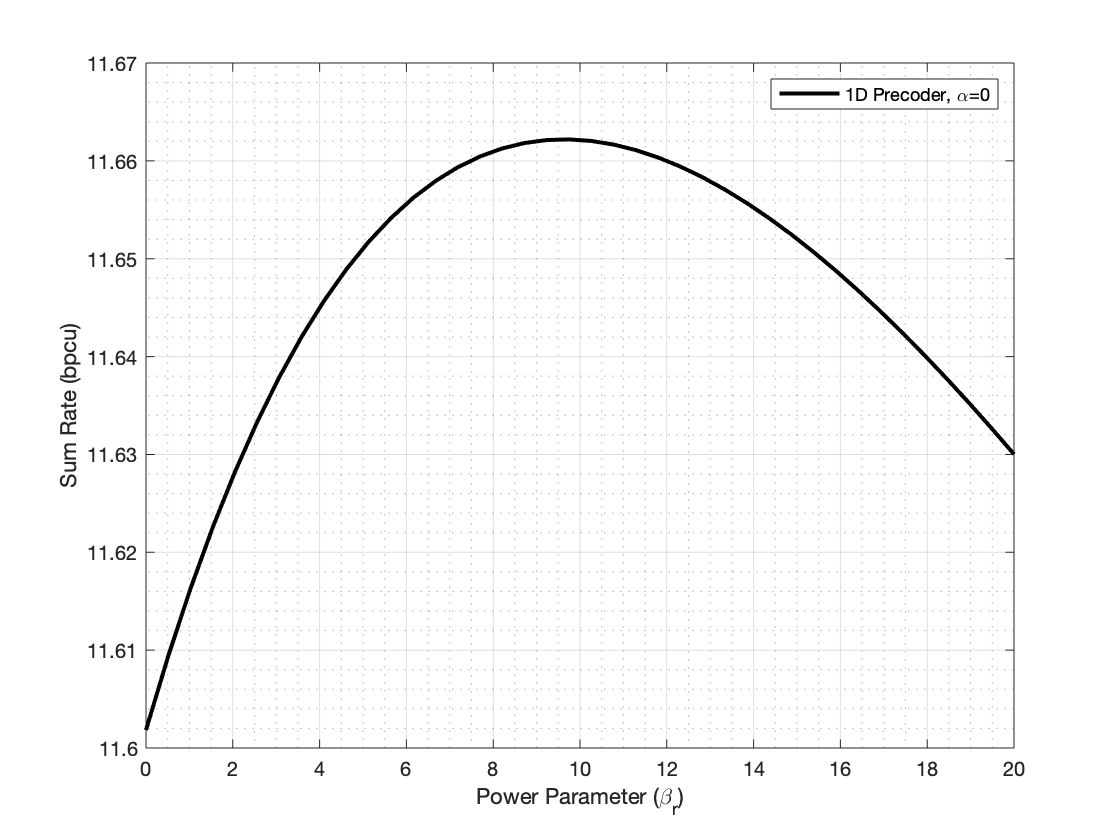

angel = strcat('\pi/', num2str(pi / mu));
if (mu == 0)
    angel = num2str(0);
end

name_a = '1D Precoder';
name_b = '2D Precoder';

name1 = strcat(name_a, ', \alpha=', num2str(alpha));
name2 = strcat(name_a, ', \eta=', num2str(eta), ', \mu=', angel);
name3 = strcat(name_b, ', \alpha=', num2str(alpha));
name4 = strcat(name_b, ', \eta=', num2str(eta), ', \mu=', angel);

x_label = 'Power Parameter (\beta_r)';
y_label = 'Sum Rate (bpcu)';

style = '-k';

figure;
plot(range, R1, style, 'DisplayName', name1);

ylabel(y_label, 'fontsize', 10);
xlabel(x_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;

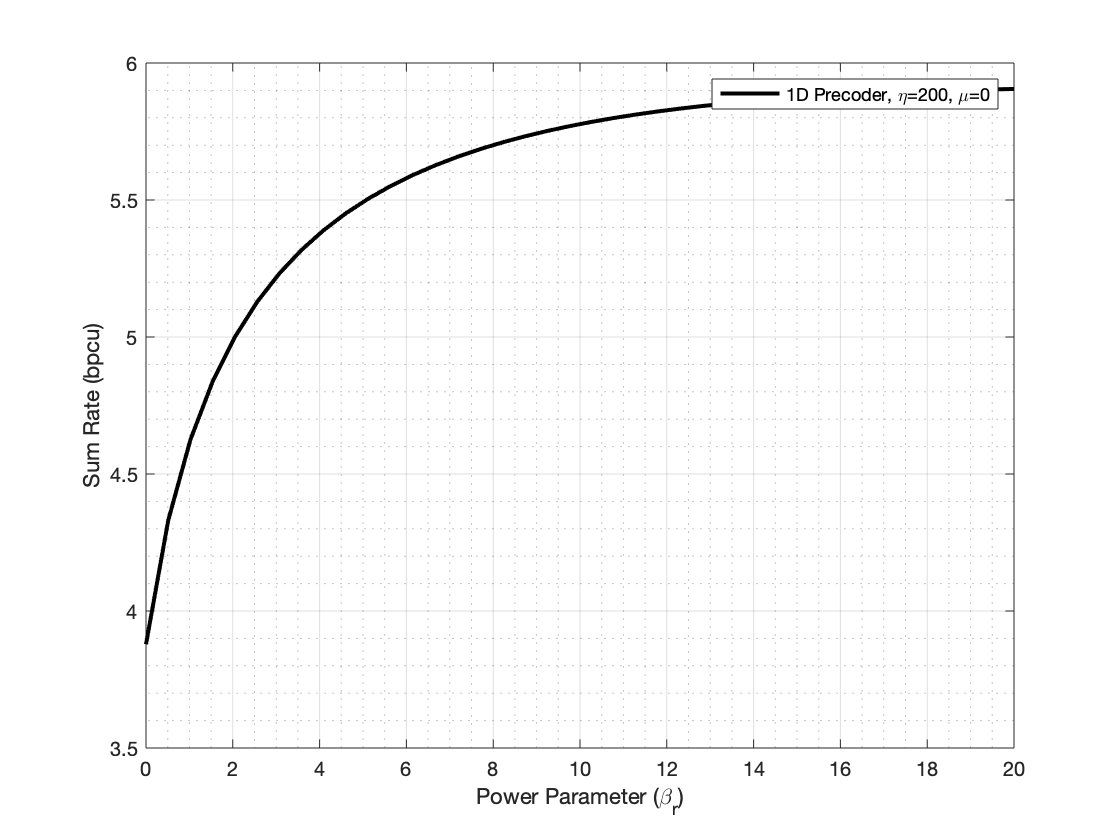



figure;
plot(range, R2, style, 'DisplayName', name2);

ylabel(y_label, 'fontsize', 10);
xlabel(x_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;

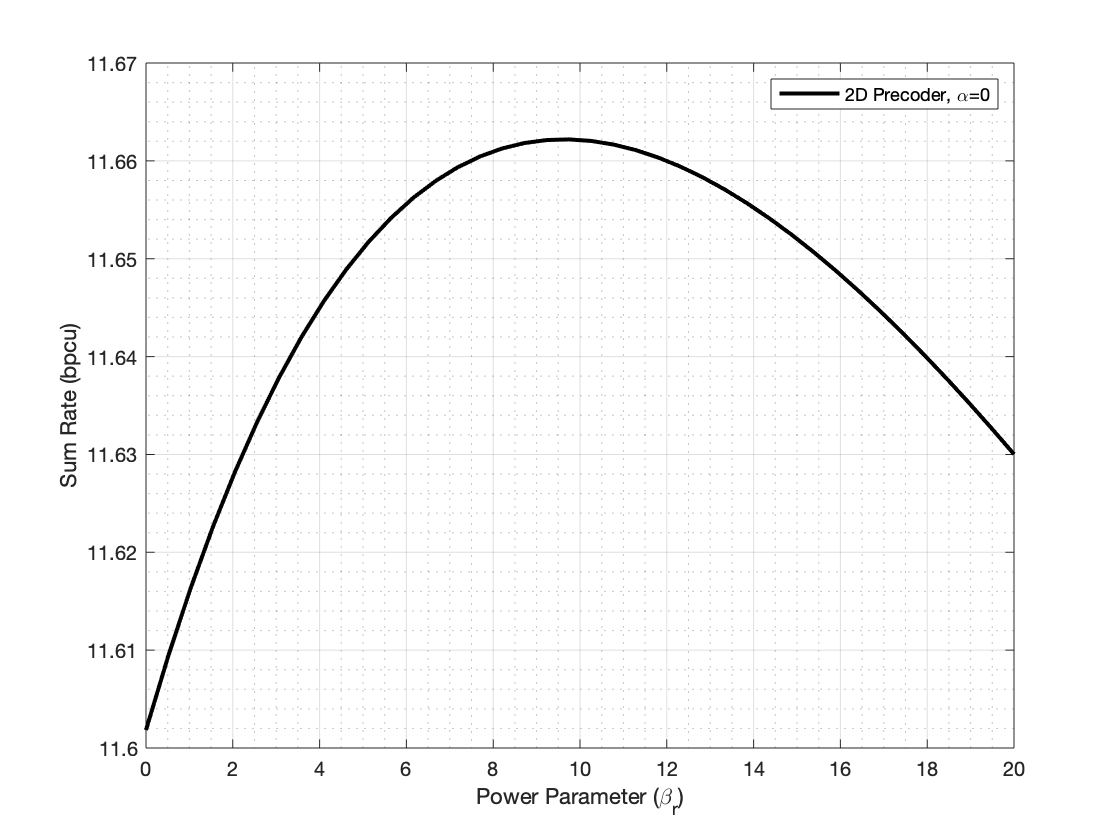


figure;
plot(range, R3, style, 'DisplayName', name3);

ylabel(y_label, 'fontsize', 10);
xlabel(x_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;

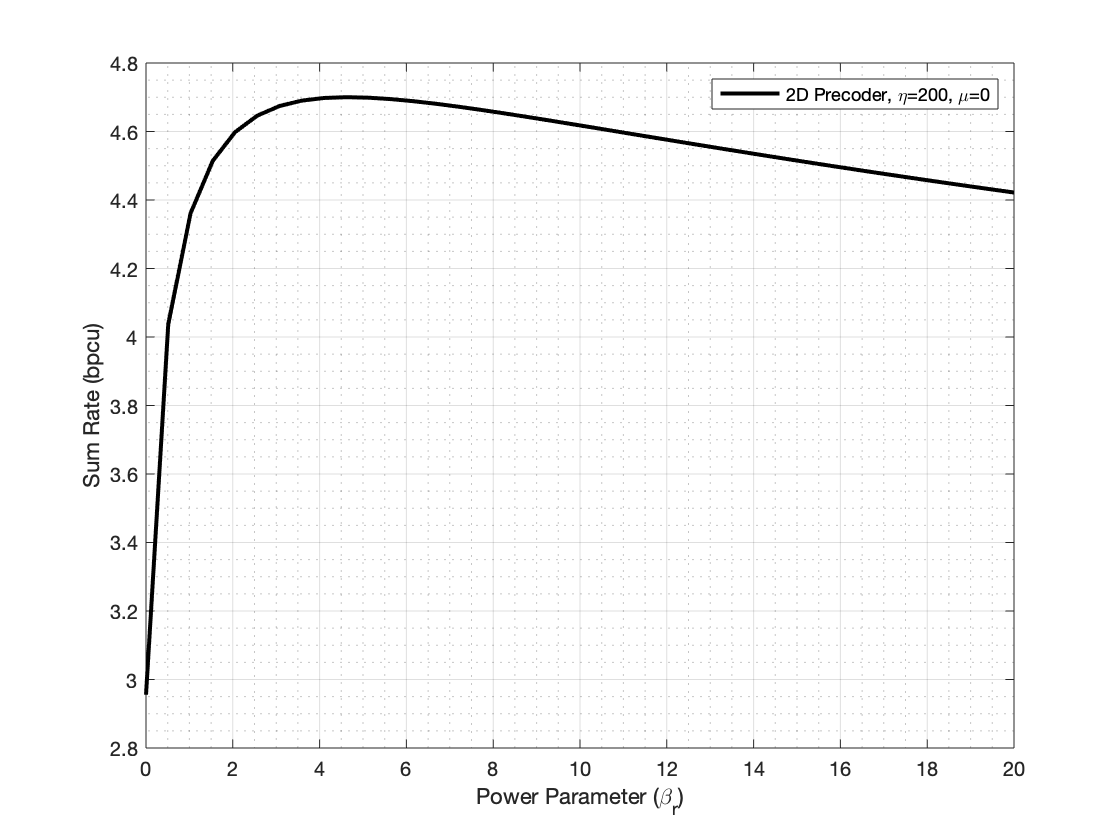



figure;
plot(range, R4, style, 'DisplayName', name4');

ylabel(y_label, 'fontsize', 10);
xlabel(x_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;